%分段三次埃米尔特插值
clear;clc
x = -10:1:10;
y = x.^2 - exp(x);
new_x = -10:0.1:10;
new_y = pchip(x,y,new_x)

new_y = 1.0e+04 *

    0.0100    0.0098    0.0096    0.0094    0.0092    0.0090    0.0088    0.0086    0.0085    0.0083    0.0081    0.0079    0.0077    0.0076    0.0074    0.0072    0.0071    0.0069    0.0067    0.0066    0.0064    0.0062    0.0061    0.0059    0.0058    0.0056    0.0055    0.0053    0.0052    0.0050    0.0049    0.0048    0.0046    0.0045    0.0044    0.0042    0.0041    0.0040    0.0038    0.0037    0.0036    0.0035    0.0034    0.0032    0.0031    0.0030    0.0029    0.0028    0.0027    0.0026


plot(x,y,'o',new_x,new_y,'r')

%三次样条插值
clear;clc
x = -10:1:10;
y = sin(x);
new_x1 = -10:0.1:10;
new_y1 = spline(x,y,new_x1)

new_y1 =     0.5440    0.4517    0.3567    0.2599    0.1618    0.0632   -0.0352   -0.1326   -0.2284   -0.3218   -0.4121   -0.4987   -0.5807   -0.6575   -0.7284   -0.7927   -0.8496   -0.8984   -0.9385   -0.9690   -0.9894   -0.9989   -0.9980   -0.9869   -0.9660   -0.9357   -0.8965   -0.8486   -0.7924   -0.7284   -0.6570   -0.5786   -0.4940   -0.4045   -0.3108   -0.2142   -0.1155   -0.0158    0.0840    0.1827    0.2794    0.3732    0.4631    0.5486    0.6289    0.7031    0.7707    0.8308    0.8827    0.9256


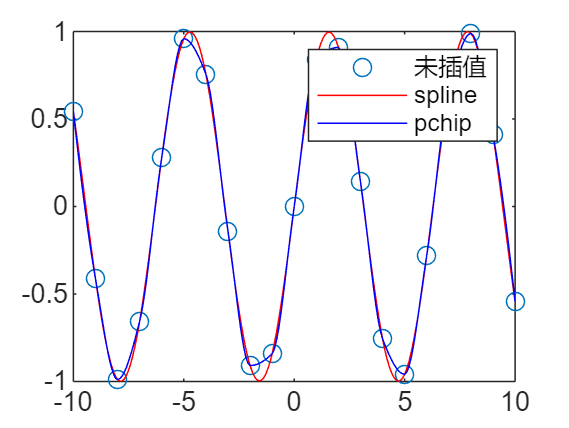

new_y2 = pchip(x,y,new_x1);

plot(x,y,'o',new_x1,new_y1,'r',new_x1,new_y2,'b')
legend('未插值','spline','pchip')

%interpn
clear;clc
